# Understand what is happening in the build expanded model

## matlab only works with specific versions of python, the latest is the version 3.7 python

clc
clear
fields_to_keep={'S','rxns', 'mets', 'metFormulas','genes', 'rules', 'grRules', 'b', 'rxnGeneMat','c', 'lb', 'ub', 'rev', 'subSystems','metFormulas'};
addpath(genpath("\\atlas.uni.lux\fstc_sysbio\0- UserFolders\Leonie.THOMAS\projects\20241230_toy_model_multi_model_construction"))
addpath(genpath("C:\Users\leonie.thomas\scFASTCORMICS"))
 %%



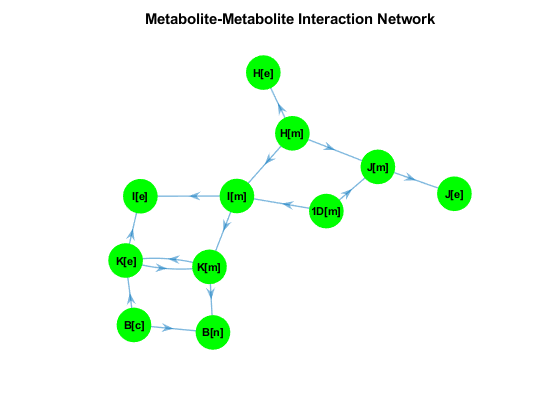



% script to load the small toy model
small_model = 1;
load_toy_model

set up of python environment: 

% %just start matlab from the conda environment then this should all be set
% %so that it works
terminate(pyenv)
pyversion("C:\Users\leonie.thomas\.conda\envs\mat_python\python")
pyenv


       version: '3.9'
    executable: 'C:\ProgramData\Anaconda3\python.EXE'
       library: 'C:\ProgramData\Anaconda3\python39.dll'
          home: 'C:\ProgramData\Anaconda3'
      isloaded: 0



pyenv('ExecutionMode','OutOfProcess')

pe =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\ProgramData\Anaconda3\python.EXE"
          Library: "C:\ProgramData\Anaconda3\python39.dll"
             Home: "C:\ProgramData\Anaconda3"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\ProgramData\Anaconda3\python.EXE"
          Library: "C:\ProgramData\Anaconda3\python39.dll"
             Home: "C:\ProgramData\Anaconda3"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


pe = pyenv;
if pe.Version == ""
    disp "Python not installed"
end

py.list({"Monday","Tuesday","Wednesday","Thursday","Friday"})

ans =   Python list with no properties.

    ['Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday']


### Start working with python and pyCobra 

- load the model with and find the different rxns types - is that the same ? 

- so expand_model_understood till line 75

%From the MATLAB command prompt, add the current folder to the Python search path.
if count(py.sys.path,'C:\Users\leonie.thomas\scFASTCORMICS\documentation') == 0
    insert(py.sys.path,int32(0),'C:\Users\leonie.thomas\scFASTCORMICS\documentation');
end

NULL pointer returned from Python.

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\ProgramData\Anaconda3\python.EXE"
          Library: "C:\ProgramData\Anaconda3\python39.dll"
             Home: "C:\ProgramData\Anaconda3"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


which py

C:\Program Files\MATLAB\R2019b\toolbox\matlab\external\interfaces\python\py.m



% py.model_expansion.theend(py.numpy.array(model))
% 
% %Create an input argument, a list of names, in MATLAB.
N = py.list({'Jones','Johnson','James'});
% 
% names = py.model_expansion.search(N)

%Create an input argument, a list of names, in MATLAB.
N = py.list({'Jones','Johnson','James'});

%p = py.numpy.array(magic(3))
%names = py.model_expansion.search(N)

% models = {model; model; model; model};
% oldOptionalOrder = {'nameTagsModels', 'modelHost', 'nameTagHost', 'mergeGenesFlag'};
% 
% 
% % Define default input parameters if not specified
% parser = inputParser();
% parser.addRequired('models', @iscell);
% parser.addParameter('nameTagsModels', {}, @iscell);
% parser.addParameter('modelHost', {}, @isstruct);
% parser.addParameter('nameTagHost', '', @(x) ischar(x) || iscell(x))
% parser.addParameter('mergeGenesFlag', false, @(x) isnumeric(x) || islogical(x))
% parser.addParameter('remCyclesFlag', false, @(x) isnumeric(x) || islogical(x))
% 
% parser.parse(models, varargin{:});
% 
% models = parser.Results.models;
% nameTagsModels = parser.Results.nameTagsModels;
% modelHost = parser.Results.modelHost;
% nameTagHost = parser.Results.nameTagHost;
% mergeGenesFlag = parser.Results.mergeGenesFlag;
% remCyclesFlag = parser.Results.remCyclesFlag;
% 
% if isempty(models)
%    error('Please enter at least one model!')
% end
% % prepare the model structures and assign name tags for each model structure if not provided
% modelNumber = size(models, 1);
% 
% if isempty(nameTagsModels)
%     % assign default name tags for microbes
%     for i = 1:modelNumber
%         nameTagsModels{i, 1} = strcat('model', num2str(i), '_');
%     end
% else
%     if size(nameTagsModels, 1) ~= modelNumber
%         error('Number of name tags and joint models needs to be identical!')
%     end
% end
% 
% if isempty(nameTagHost)
%     % assign default name tag for host
%     nameTagHost = 'Host_';
% end
% 
% %% ensure compatibility with reconstructions from BIGG Models database
% for i = 1:modelNumber
%     model = models{i, 1};
%     metIndices =~cellfun(@isempty, regexp(model.mets, '_e$'));
%     model.mets(metIndices) = strrep(model.mets(metIndices), '_e', '[e]');
%     models{i, 1} = model;
% end
% if ~isempty(modelHost)
% metIndices =~cellfun(@isempty, regexp(modelHost.mets, '_e$'));
% modelHost.mets(metIndices) = strrep(modelHost.mets(metIndices), '_e', '[e]');
% end
% 
% %% Ensure compatibility with reconstructions from KBase database
% for i = 1:modelNumber
%     model = models{i, 1};
%     metIndices =~cellfun(@isempty, regexp(model.mets, '\[e0\]$'));
%     model.mets(metIndices) = strrep(model.mets(metIndices), '[e0]', '[e]');
%     % need workaround for biomass metabolite, otherwise the resulting joint
%     % model will be unable to carry biomass flux
%     if ~isempty(find(ismember(model.mets, 'cpd11416[c0]')))
%         model = addDemandReaction(model, 'cpd11416[c0]');
%     end
%     models{i, 1} = model;
% end
% if ~isempty(modelHost)
% metIndices =~cellfun(@isempty, regexp(modelHost.mets, '\[e0\]$'));
% modelHost.mets(metIndices) = strrep(modelHost.mets(metIndices), '[e0]', '[e]');
% end
% %% Remove futile cycles that may appear after joining (optional)
% if remCyclesFlag
%     database = loadVMHDatabase;
% 
%     unionRxns={};
%     for i = 1:modelNumber
%         model=models{i, 1};
%         unionRxns=vertcat(unionRxns,model.rxns);
%     end
%     unionRxns=unique(unionRxns);
%     for i = 1:modelNumber
%         model=models{i, 1};
%         model = removeFutileCycles(model, biomasses{i}, database,unionRxns);
%         models{i, 1} = model;
%     end
% end
% %% define some variables
% eTag = 'u';
% exTag = 'e';
% % find exchange reactions for models, but leaves demand and sink reactions
% % do this for all models to be added, remove exchange reactions from host while leaving demand and sink reactions
% % First, find the minimal number of fields common to all models.
% presentinallModels = fieldnames(models{1});
% missingFields = {};
% for i = 2:modelNumber
%     cfields = fieldnames(models{i});
%     missingFields = union(missingFields, setxor(cfields, presentinallModels));
%     presentinallModels = intersect(presentinallModels, cfields);
% end
% fprintf('The following fields are missing in several models, they will not be merged:\n');
% disp(missingFields);
% models = restrictModelsToFields(models, presentinallModels);
% 
% modelStorage = cell(modelNumber, 1);
% for i = 1:modelNumber
%     % a new model each turn
%     model = models{i, 1};
%     % find exchange reactions and external metabolites
%     exmod = model.rxns(strmatch('EX', model.rxns));
%     % remove all previously defined exchange reactions
%     model = removeRxns(model, exmod);
%     % make sure the exchange reactions and changed model are saved under correct name
%     modelStorage{i, 1} = model;
% end
% 
% if ~isempty(modelHost)
%     %% with a host
%     exmod = modelHost.rxns(strmatch('EX', modelHost.rxns));
% 
%     % modelHost = removeRxns(modelHost,ExRH);
%     % ExRH = modelHost.rxns(selExcH);
%     % ExRH(strmatch('sink',modelHost.rxns(selExcH)))=[];
%     % ExRH(strmatch('DM',modelHost.rxns(selExcH)))=[];
% 
%     % create a new extracellular space for host
%     % find all metabolites in e
%     relMetIndex = cellfun(@(x) ~isempty(strfind(x, '[e]')), modelHost.mets);
%     relMets = modelHost.mets(relMetIndex);
%     relRxns = findRxnsFromMets(modelHost, relMets);  % These are all reactions which are relevant
%     rxnIndices = ismember(modelHost.rxns, relRxns);
%     Stoich = modelHost.S(:, rxnIndices);
%     changedMets = regexprep(modelHost.mets, '\[e\]', '\[b\]');
%     modelHost = addMultipleMetabolites(modelHost, setdiff(changedMets, modelHost.mets));
%     modelHost = addMultipleReactions(modelHost, strcat(modelHost.rxns(rxnIndices), 'b'), changedMets, Stoich, 'lb', modelHost.lb(rxnIndices), ...
%                                     'ub', modelHost.ub(rxnIndices), 'c', modelHost.c(rxnIndices), 'subSystems', repmat({'Host Exchange'}, numel(relRxns), 1));
% 
%     % remove exchange reactions from host while leaving demand and sink reactions
%     modelHost = removeRxns(modelHost, exmod);
% 
%     %% create intercellular space
%     % will need to find all extracellular metabolites and duplicate reactions
%     % if a host model was input, create the shared compartment for the microbes
%     model = modelStorage{1, 1};
%     nameTag = nameTagsModels{1, 1};
%     [modelJoint, MexGJoint] = createInterSpace(model, nameTag, eTag, exTag);
% 
%     % if more than one microbe was input
%     if modelNumber > 1
%         for i = 1:modelNumber
%             model = modelStorage{i, 1};
%             nameTag = nameTagsModels{i, 1};
%             [model, MexG] = createInterSpace(model, nameTag, eTag, exTag);
%             % make sure the changed model is saved under correct name
%             modelStorage{i, 1} = model;
%             MexGJoint = union(MexG, MexGJoint);
%         end
%      end
% 
%     [modelHost,MexGHost] = createInterSpace(modelHost, nameTagHost, eTag, exTag);
%     MexGJoint = union(MexGJoint, MexGHost);
% 
%     %% merge the models
%     % if more than one microbe was input
%     if modelNumber > 1
%         for i = 2:modelNumber
%             model = modelStorage{i, 1};
%             [modelJoint] = mergeTwoModels(modelJoint, model, 1, mergeGenesFlag);
%         end
%     end
%     [modelJoint] = mergeTwoModels(modelJoint,modelHost, 1, mergeGenesFlag);
% 
%     modelJoint = addExchangeRxn(modelJoint, unique(MexGJoint));
% 
% else
%     %% without a host
%      % create the shared compartment for the microbes
%     model = modelStorage{1, 1};
%     nameTag = nameTagsModels{1, 1};
%     [modelJoint, MexGJoint] = createInterSpace(model, nameTag, eTag, exTag);
%      if modelNumber > 1
%         for i = 2:modelNumber
%             model = modelStorage{i, 1};
%             nameTag = nameTagsModels{i, 1};
%             [model, MexG] = createInterSpace(model, nameTag, eTag, exTag);
%             modelStorage{i, 1}=model;
%             MexGJoint = union(MexG, MexGJoint);
%         end
%      end
% 
%      if modelNumber > 1
%         for i = 2:modelNumber
%             model = modelStorage{i, 1};
%             [modelJoint] = mergeTwoModels(modelJoint, model, 1, mergeGenesFlag);
%         end
%      end
% 
%     modelJoint = addExchangeRxn(modelJoint, unique(MexGJoint));
% end
% end
% 
% %%
% function [modelNew,MexG] = createInterSpace(model, nameTag, eTag, exTag)
% % create intercellular space
% % will need to find all extracellular metabolites and duplicate reactions using them
% modelNew = model;
% % add name tag to all metabolites and reactions in model
% modelNew.mets = strcat(nameTag, model.mets);
% modelNew.rxns = strcat(nameTag, model.rxns);
% % Get the relevant metabolites
% relMetsIndex = cellfun(@(x) ~isempty(strfind(x,'biomass[c]')) || ~isempty(strfind(x,['[', exTag, ']'])),modelNew.mets);
% relMets = modelNew.mets(relMetsIndex);
% % Define the names of the interspace metabolites
% MexG = regexprep(strrep(relMets,nameTag,''),strcat('\[', exTag, '\]'), strcat('\[', eTag, '\]'));
% varinput = {};
% % Add metNames and metFormulas, if present in the original model
% if isfield(modelNew,'metNames')
%     varinput{end+1} = 'metNames';
%     varinput{end+1} = modelNew.metNames(relMetsIndex);
% end
% if isfield(modelNew,'metFormulas')
%     varinput{end+1} = 'metFormulas';
%     varinput{end+1} = modelNew.metFormulas(relMetsIndex);
% end
% % Add all new Metabolites
% modelNew = addMultipleMetabolites(modelNew, MexG, varinput{:});
% 
% nExchange = numel(relMets);
% % Set the exchanger Stoichiometries (met[e] -> met[u])
% stoich = [-speye(nExchange);speye(nExchange)];
% % Set the names of the exchangers
% rxnNames =  strcat(nameTag, 'IEX_', MexG, 'tr');
% % Set the bounds
% lbs = repmat(-1000,nExchange,1);
% ubs = repmat(1000,nExchange,1);
% % Set the subSystem
% subSystems = repmat({'Transport, intercellular'},nExchange,1);
% % Add all Reactions in one go.
% modelNew = addMultipleReactions(modelNew,rxnNames,[relMets;MexG],stoich,'lb',lbs,'ub',ubs,'subSystems',subSystems);
% end

% 
% nameTagsModel = {'Ec1'; 'Ec2'; 'Ec3'; 'Ec4'};
% EcCom = createMultipleSpeciesModel({model; model; model; model}, nameTagsModel);

% model = EcCom; 
% graphObj=createMetIntrcNetwork(model,model.mets);
% set(gcf,'Visible','on'); % produce figure as pop up since live editor does

% model.genes=regexprep(model.genes,'\.[0-9]+$','');
% % get external rxns - searching the S matrix for columns with only one
% % entry - 1 entry 
% exRxns=find(sum(abs(model.S),1)==1);
% % find the corrsponding metabolite -> through S matrix
% [exmets,~]=find(model.S(:, exRxns));
% % from all the metabolites which are participating in the exchange rxns,
% % only the ones should be choosen which are in the e compartment, not the
% % metabolites within the cell -> therefore filtering for [e]
% exmets=exmets(contains(model.mets(exmets),'[e]'));
% exmets=unique(model.mets(exmets));
% % find the index within the model.mets
% [~,exmetsID,~]=intersect(model.mets, exmets);
% % find again the corresponding rxns
% [~,r]=find(model.S(exmetsID,:));
% % make sure that the found rxns are ex rxns found in the beginning
% exRxns=intersect(exRxns,r);
% % find the names from the indices
% exRxns=model.rxns(exRxns);
% 
% u_mets=unique(regexprep(exmets,'\[e]','[u]'));

% adding one node ! and
%model_pool = model;
%model_pool.S = [[model_pool.S,sparse(size(model_pool.S,1),1)];-1*ones(1,size([model_pool.S,sparse(size(model_pool.S,1),1)],2))];
%model_pool.mets = [model_pool.mets;'pool'];
%model_pool.rxns = [model_pool.rxns;'pool'];
%graphObj=createMetIntrcNetwork(model,model.mets);
%set(gcf,'Visible','on'); % produce figure as pop up since live editor does

%expand_model_understood
%size(model.S)


o20241231_investigate_multiple_population_building

this code creates compartments with 3 cellclusters and the second time it is expanded it creates different compartments 


load_toy_model


%% PUTTING RXNS ARRAY TOGETHER AND INTO THE RIGHT SLOT 


% after looping over the slots separatly and creating a array for all the
% different rxns types: internal, transport, intercluster_transport and
% exchange - this section then puts them all togehter and assigns them into
% the correct slot in the model object
for ii=1:numel(fields)
    if size( model.(fields{ii}),1)==size( model.rxns,1) && size( model.(fields{ii}),1)~=size( model.mets,1)
        if iscell(expanded_input_model.(fields{ii}))
            
            rul=[internal_rxns_array(:,ii+1);intercluster_trans_array(:,ii+1);cell(numel(trans),1);cell(numel(Ex),1)];
            rul(cellfun('isempty',rul))=cellstr('');
            expanded_input_model.(fields{ii})=rul;
            
        else
            if strcmp(fields{ii}, 'lb')
                
                %% lower bounds set -1000 by defaut for trans and Ex
                expanded_input_model.(fields{ii})=[internal_rxns_array_n(:,ii+1);intercluster_trans_array_n(:,ii+1);ones(numel(trans),1)*-1000; ones(numel(Ex),1)*-1000];
            else
                % c & rev  - why median ? 
                expanded_input_model.(fields{ii})=[internal_rxns_array_n(:,ii+1);intercluster_trans_array_n(:,ii+1);ones(numel(trans),1)*median(internal_rxns_array_n(:,ii+1)); ones(numel(Ex),1)*median(internal_rxns_array_n(:,ii+1))];
            end
        end
    else
        if iscell(expanded_input_model.(fields{ii}))
            [~,index]=ismember(exmets,model.mets);
            temp2=cell(numel(exmets),1);
            temp=model.(fields{ii});
            temp2(index>0)=temp(index(index>0));
            expanded_input_model.(fields{ii})=[expanded_input_model.(fields{ii});temp2;temp2];
        else
            % b slot - why the mean ? 
            expanded_input_model.(fields{ii})=[expanded_input_model.(fields{ii});ones(numel(umets),1)*mean(expanded_input_model.(fields{ii}));ones(numel(umets),1)*mean(expanded_input_model.(fields{ii}))];
        end
    end
end


 table(expanded_input_model.S)



%% FINALIZING THE RXNS SLOT IN THE EXPANDED MODEL

% creating a Trans and Ex rxn for every ex met in u compartment
trans=strcat('Trans_',sort(exmets));
Ex=strcat('Ex_',exmets);
dico_EX=cell(numel(Ex),2);
dico_EX(:,1)=Ex;
% find the rxns for the ex mets 
for i=1:numel(exmets)
    r=find(model.S(ismember(model.mets,exmets(i)),:));
    r=intersect(model.rxns(r),exRxns);
    dico_EX(i,2)=r;
end
% add all the rxns to the rxns slot of the model
expanded_input_model.rxns=[internal_rxns_array(:,1);intercluster_trans_array(:,1);trans;Ex];

%% PUTTING RXNS ARRAY TOGETHER AND INTO THE RIGHT SLOT + Adding the missing information about Exchange and Transport rxns


for ii=1:numel(fields)
    if size( model.(fields{ii}),1)==size( model.rxns,1) && size( model.(fields{ii}),1)~=size( model.mets,1)
        if iscell(expanded_input_model.(fields{ii}))
            
            rul=[internal_rxns_array(:,ii+1);intercluster_trans_array(:,ii+1);cell(numel(trans),1);cell(numel(Ex),1)];
            rul(cellfun('isempty',rul))=cellstr('');
            expanded_input_model.(fields{ii})=rul;
            
        else
            if strcmp(fields{ii}, 'lb')
                
                %% lower bounds set -1000 by defaut for trans and Ex
                expanded_input_model.(fields{ii})=[internal_rxns_array_n(:,ii+1);intercluster_trans_array_n(:,ii+1);ones(numel(trans),1)*-1000; ones(numel(Ex),1)*-1000];
            else
                % c & rev  - why median ? 
                expanded_input_model.(fields{ii})=[internal_rxns_array_n(:,ii+1);intercluster_trans_array_n(:,ii+1);ones(numel(trans),1)*median(internal_rxns_array_n(:,ii+1)); ones(numel(Ex),1)*median(internal_rxns_array_n(:,ii+1))];
            end
        end
    else
        if iscell(expanded_input_model.(fields{ii}))
            [~,index]=ismember(exmets,model.mets);
            temp2=cell(numel(exmets),1);
            temp=model.(fields{ii});
            temp2(index>0)=temp(index(index>0));
            expanded_input_model.(fields{ii})=[expanded_input_model.(fields{ii});temp2;temp2];
        else
            % b slot - why the mean ? 
            expanded_input_model.(fields{ii})=[expanded_input_model.(fields{ii});ones(numel(umets),1)*mean(expanded_input_model.(fields{ii}));ones(numel(umets),1)*mean(expanded_input_model.(fields{ii}))];
        end
    end
end

%% correct reversibility - 
lb=zeros(numel(exmets),1);
ub=zeros(numel(exmets),1);
grRules=cell(numel(exmets),1);
R_ex=cell(numel(exmets),1);
% since the ex rxns are still defined as 1 in the s matrix the sign needs
% to be flipped - toy model convention ? Recon convention ???
for i=1:numel(exmets)
    [~,r]=find(model.S(ismember(model.mets,exmets(i)),:));
    r=intersect(model.rxns(r),exRxns);
    R_ex(i,1)=r;
    
    sign=model.S(ismember(model.mets,exmets(i)),ismember(model.rxns,r));
    if full(sign) >0
        % then flip
        model.S(ismember(model.mets,exmets(i)),ismember(model.rxns,r))=-sign;
        tmp=model.ub(ismember(model.rxns,r));
        model.ub(ismember(model.rxns,r))=-model.lb(ismember(model.rxns,r));
        model.lb(ismember(model.rxns,r))=-tmp;
    end
end
% this part I do not get... - 
% so we create lb and ub with all zeros, then we manibulate this 
% we get the indices of the R_ex in the model.rxns 
[~,index]=ismember(R_ex,model.rxns);
% then we filter out all the R_ex which are not in the model.rxns by
% excluding the zero entrie in the indices vector
lb(index>0)=model.lb(index(index>0));
ub(index>0)=model.ub(index(index>0));
% transfer the lb & ub from the consensus model to the expanded model, the
% indices of the ex rxns change between those two models, therefore this
% transfer is needed

Table_bound=table(R_ex,lb, ub, exmets,strcat('Ex_',exmets));
[~,index]=ismember(expanded_input_model.rxns,table2array(Table_bound(:,5)));
expanded_input_model.lb(index>0)=Table_bound.lb(index(index>0));
expanded_input_model.ub(index>0)=Table_bound.ub(index(index>0));



%%
% now the reversibility slot is fixed, for all the rxns the lb were set,
% so for the rxns which have a negative lb we can assume that they are
% reversible 
expanded_input_model.rev= sparse(numel(expanded_input_model.rxns),1);
expanded_input_model.rev(expanded_input_model.lb<0)=1;


%%
% building the RxnGene matrix from grRules slot
expanded_input_model = buildRxnGeneMat(expanded_input_model);
% creating the .rule slot from grRules
expanded_input_model = creategrRulesField(expanded_input_model);
% fixing Irr rxns ? what does that mean? 
expanded_input_model=fixIrr_rFASTCORMICS(expanded_input_model);

% % this is the fixIrr function code: 
% model.rev = zeros(numel(model.rxns),1);
% % the  
% model.rev(model.lb <0 & model.ub> 0) = 1;
% Irr=(model.lb >=0 & model.ub>0| model.ub<=0 & model.lb<0);
% model.rev(Irr) = 0;
% FakeIrr= model.ub <=0 & model.lb<0;
% model.S(:, FakeIrr) = -model.S(:,FakeIrr);
% model.ub(FakeIrr) = -model.lb(FakeIrr);
% model.lb(FakeIrr) = zeros(sum(FakeIrr),1);

%% 
% correct rules for exchanges
% question: the exchange rxns are empty bevore and after -> 
% first of all, why do this code in the frist place and why should exhange
% reactions have a gprule ? 

[~,index]=ismember(R_ex,model.rxns);
grRules(index>0)=model.grRules(index(index>0));
% getting the rules for the exchange rxns from the consistent generic model
% then adding to the table for the exchange reactions 
Table_bound=[Table_bound,table(grRules)];
rules_keep=cell(size(Table_bound,1),1);
for counter2=1:size(Table_bound,1)
    if ~cellfun('isempty',table2array(Table_bound(counter2,6)))
        
        
        for counter=1:number_of_cluster
            if counter==1
                rules=strcat(table2array(Table_bound(counter2,6)),'_', num2str(counter));
            else
                tmp= strcat(table2array(Table_bound(counter2,6)),'_',num2str(counter));
                rules=strcat(string(rules), ' or ','$ ', string(tmp));
            end
        end
        rules=strrep(rules,'$',' ');
        rules_keep(counter2,1)=cellstr(rules);
    end
    [~,index]=ismember(expanded_input_model.rxns,table2array(Table_bound(:,5)));
    

    expanded_input_model.grRules(index>0)=rules_keep(index(index>0),1);
end
    expanded_input_model.grRules(cellfun('isempty',expanded_input_model.grRules))=cellstr('');
for i=1:numel(expanded_input_model.grRules)
expanded_input_model.grRules(i)=strrep(expanded_input_model.grRules(i),'or',' or ');
     expanded_input_model.grRules(i)=strrep(expanded_input_model.grRules(i),'and',' and ');
end

% update the rules field after altering the grRules slot
expanded_input_model = generateRules(expanded_input_model);




expanded_input_model

expanded_input_model = buildRxnGeneMat(expanded_input_model);

alternative code, up until now it only pasts together the S matrix....a lot more is needed to replicate the script!!

%%% new code from me - to produce the matrices
% int = expand_matrix(eye(number_of_cluster),internal_S_matrix_for_1_cluster);
% int_trans_Smat = expand_matrix(eye(number_of_cluster),intercluster_trans_Smat_4_1_cluster);
% int_trans_Smat2 = expand_matrix([1,1],intercluster_trans_Smat_4_1_cluster2);
% 
% layout_matrix_rxns = "_" + [1:number_of_cluster]; 
% layout_matrix_rxns = [layout_matrix_rxns',repmat("",number_of_cluster,numel(fields))];
% int_rxns_array = expand_matrix(layout_matrix_rxns,internal_rxns);
% int_trans_array = expand_matrix(layout_matrix_rxns,intercluster_transport);
% met = expand_matrix("_" + [1:number_of_cluster]',internal_mets)';
% expanded_genes = expand_matrix("_" + [1:number_of_cluster]',model.genes); 


varname = regexp(exmets, '\[(.*?)\]', 'match', 'once');
expanded_input_model.mets=[mets';sort(strrep(exmets,varname,'[u]'));sort(strrep(exmets,varname,'[e]'))];
umets=strrep(exmets,varname,'[u]');
S=[internal_S_matrix,intercluster_trans_Smat];

S2=[sparse(size(umets,1),size(internal_S_matrix,2)),intercluster_trans_Smat2];
S=[S;S2];
S7=sparse(size(intercluster_trans_Smat,1), numel(exRxns));
S8=[S7;eye(size(intercluster_trans_Smat2,1))*-1];
S2=[S;sparse(size(intercluster_trans_Smat2,1),size(S,2))];
S=[S2, [S8;eye(size(intercluster_trans_Smat2,1))]];

S7=sparse(size(S,1), numel(exRxns));
S7(end+1-size(eye(size(intercluster_trans_Smat2,1)),1):end,:)=eye(size(intercluster_trans_Smat2,1));
S=[S, S7];


expanded_input_model.S=S;
trans=strcat('Trans_',sort(exmets));
Ex=strcat('Ex_',exmets);
dico_EX=cell(numel(Ex),2);
dico_EX(:,1)=Ex;
for i=1:numel(exmets)
    r=find(model.S(ismember(model.mets,exmets(i)),:));
    r=intersect(model.rxns(r),exRxns);
    dico_EX(i,2)=r;
end
expanded_input_model.rxns=[internal_rxns_array(:,1);intercluster_trans_array(:,1);trans;Ex];



for i=1:number_of_cluster
    % genes are copied per cluster with a postfix indicating which cluster
    % they belong to 
    expanded_input_model.genes=[expanded_input_model.genes;strcat(model.genes,'_', num2str(i))];
    
    if i>1
        ind=ind2+1;
        ind3=ind4+1;
        ind5=ind6+1;
        ind7=ind8+1;
    end
    ind2=ind+size(internal_S_matrix_for_1_cluster,1)-1;
    ind4= ind3+ size(internal_S_matrix_for_1_cluster,2)-1;
    ind6=ind5+size(intercluster_trans_Smat_4_1_cluster,1)-1;
    ind8=ind7+size(intercluster_trans_Smat_4_1_cluster,2)-1;    
    ind10=ind9+size(intercluster_trans_Smat_4_1_cluster2,1)-1;
    internal_S_matrix(ind: ind2,ind3:ind4)=internal_S_matrix_for_1_cluster;
    intercluster_trans_Smat(ind5:ind6,ind7:ind8)=intercluster_trans_Smat_4_1_cluster;
    intercluster_trans_Smat2(ind9:ind10,ind7:ind8)=intercluster_trans_Smat_4_1_cluster2;
    internal_rxns_array(ind3:ind4,1)=strcat(internal_rxns,'_', num2str(i));
    mets(ind: ind2)=strcat(internal_mets,'_', num2str(i));
    intercluster_trans_array(ind7:ind8,1)=(strcat(intercluster_transport,'_', num2str(i)));
   % do first metabolites
    for ii=1:numel(fields)
        disp("hello")
        %  here we check if the slot of the model object characterizes the
        %  rxns or the metabolites 
        if size( model.(fields{ii}),1)==size( model.mets,1)&& size( model.(fields{ii}),2)~=size( model.rxns,1)
            % if the rows are equal to the met dimension, then we add the
            % information about the corresponding slot of the
            % internal_mets
            temp=model.(fields{ii});
           
            expanded_input_model.(fields{ii})= [expanded_input_model.(fields{ii});temp(internal_mets_index)];
        elseif size( model.(fields{ii}),1)==size( model.rxns,1) && size( model.(fields{ii}),1)~=size( model.mets,1)
            % put this into a function!
            temp=model.(fields{ii});
            if strcmp(fields{ii},'rules') && i>1
                disp("going into the rules!!")
                %Update the indices of the genes in the rules. The number of total genes is added to the indices for
                %each cluster (i.e 22 + numel(model.genes) * number of
                %clusters. This is done in two steps, the expression is
                %changed. Plus (+) appear in the expressions then it is
                %evaluated to remove the (+)
                
                temp=strrep(temp, 'x(', strcat( 'x(' ,num2str(numel(model.genes)*(i-1)),'+'));
                for counter1=1:numel(temp) 
                    temp2=temp{counter1};
                    plus_pos=strfind(temp2,'+');
                    if ~isempty(plus_pos)
                        bracket1_pos=strfind(temp2,'(');
                        bracket2_pos=strfind(temp2,')');
                        if numel(plus_pos)==1 && numel(bracket2_pos)==1 && numel(bracket1_pos)==1
                            
                            temp3=temp2(bracket1_pos+1: bracket2_pos-1);
                            temp4=eval(temp3);
                            temp{counter1}=strrep(temp2,temp3, num2str(temp4));
                        else
                            while ~isempty(plus_pos)
                                
                                u22= plus_pos(1)-bracket1_pos;
                                u22=bracket1_pos(u22== min(u22(u22>0)));
                                u33= bracket2_pos-plus_pos(1);
                                u33=bracket2_pos(u33== min(u33(u33>0)));
                                temp3=temp2(u22+1: u33-1);
                                temp4=eval(temp3);
                                temp3a=strcat('(',temp3,')');
                                temp4a=strcat('(',num2str(temp4),')');
                                temp2=strrep(temp2,temp3a,temp4a);
                                plus_pos=strfind(temp2,'+');
                                bracket1_pos=strfind(temp2,'(');
                                bracket2_pos=strfind(temp2,')');
                            end
                            temp{counter1}=temp2;
                        end
                    end
                end
            else
            end
            if iscell(temp)
                internal_rxns_array(ind3:ind4,ii+1)=temp(internal_rxns_index);
                intercluster_trans_array(ind7:ind8,ii+1)=temp(intercluster_transportID);
            else
                internal_rxns_array_n(ind3:ind4,ii+1)=temp(internal_rxns_index);
                if strcmp(fields{ii}, 'lb')
                    
                    intercluster_trans_array_n(ind7:ind8,ii+1)=temp(intercluster_transportID);
                else
                    intercluster_trans_array_n(ind7:ind8,ii+1)=temp(intercluster_transportID);
                end
                
            end
            
            expanded_input_model.(fields{ii})= [expanded_input_model.(fields{ii});temp(internal_rxns_index)];
            
        end
    end
    
end

varname = regexp(exmets, '\[(.*?)\]', 'match', 'once');
expanded_input_model.mets=[mets';sort(strrep(exmets,varname,'[u]'));sort(strrep(exmets,varname,'[e]'))];
umets=strrep(exmets,varname,'[u]');
S=[internal_S_matrix,intercluster_trans_Smat];
S2=[sparse(size(umets,1),size(internal_S_matrix,2)),intercluster_trans_Smat2];
S=[S;S2];



S7=sparse(size(intercluster_trans_Smat,1), numel(exRxns));
S8=[S7;eye(size(intercluster_trans_Smat2,1))*-1];
S2=[S;sparse(size(intercluster_trans_Smat2,1),size(S,2))];
S=[S2, [S8;eye(size(intercluster_trans_Smat2,1))]];



S7=sparse(size(S,1), numel(exRxns));
S7(end+1-size(eye(size(intercluster_trans_Smat2,1)),1):end,:)=eye(size(intercluster_trans_Smat2,1));
S=[S, S7];
size(S7)

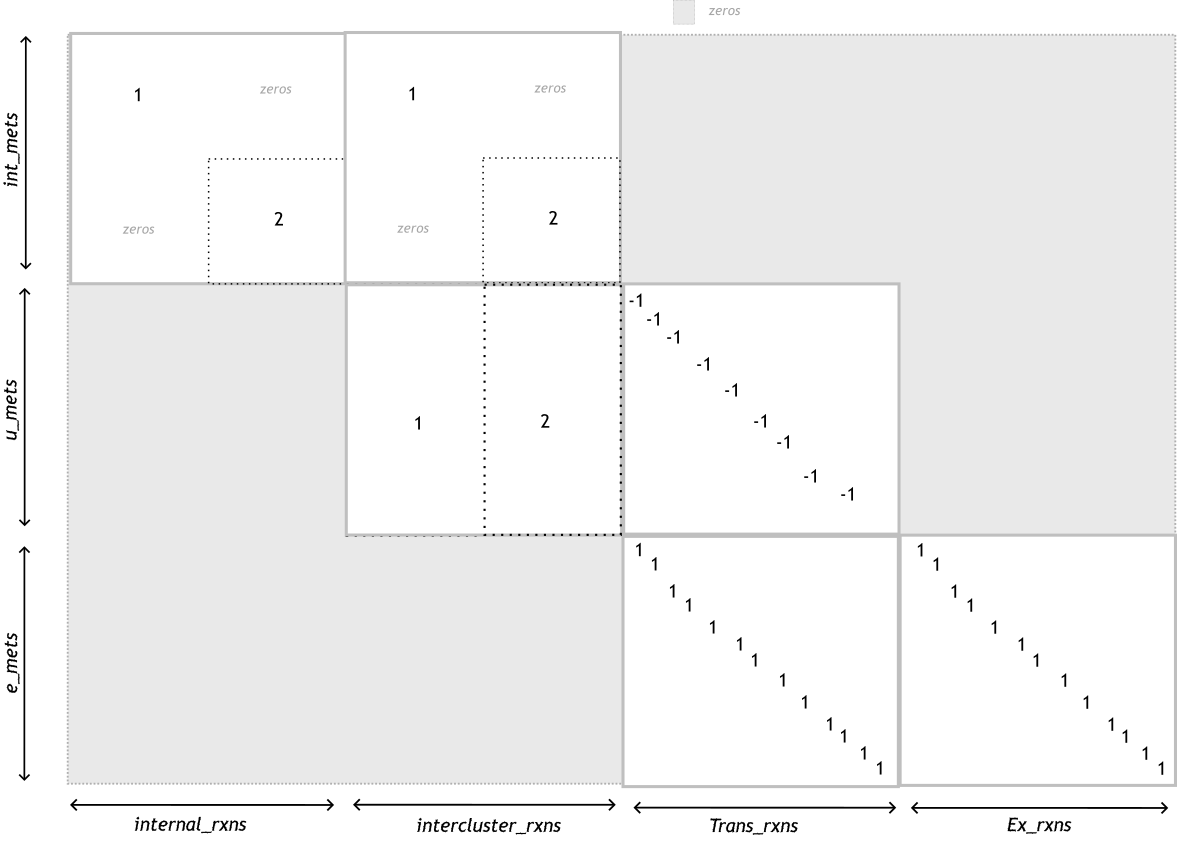


expanded_input_model.S=S;
trans=strcat('Trans_',sort(exmets));
Ex=strcat('Ex_',exmets);
dico_EX=cell(numel(Ex),2);
dico_EX(:,1)=Ex;
for i=1:numel(exmets)
    r=find(model.S(ismember(model.mets,exmets(i)),:));
    r=intersect(model.rxns(r),exRxns);
    dico_EX(i,2)=r;
end
expanded_input_model.rxns=[internal_rxns_array(:,1);intercluster_trans_array(:,1);trans;Ex];

graphObj=createMetIntrcNetwork(expanded_input_model,expanded_inpaut_model.mets);
expanded_input_model.rxns

two_rasters_model = expanded_input_model;
two_rasters_model.S = [expanded_input_model.S,zeros(size(expanded_input_model.S,1),size(expanded_input_model.S,2));
                       zeros(size(expanded_input_model.S,1),size(expanded_input_model.S,2)),expanded_input_model.S];
two_rasters_model.rxns = cellstr([expanded_input_model.rxns + "_u1"; expanded_input_model.rxns + "_u2" ;umets + "_c"]);
two_rasters_model.mets = cellstr([expanded_input_model.mets + "_u1"; expanded_input_model.mets + "_u2" ;umets + "_c"]);

two_rasters_model.S = [two_rasters_model.S,zeros(size(two_rasters_model.S,1), size(umets,1));
                            zeros(size(umets,1),size(two_rasters_model.S,2)),eye(size(umets,1))]


size(two_rasters_model.S)

two_rasters_model.b = [];
two_rasters_model.c = [];
two_rasters_model.genes = [];
two_rasters_model.grRules = [];
two_rasters_model.lb = [];
two_rasters_model.rev = [];
two_rasters_model.rules = [];
two_rasters_model.rxnGeneMat = [];
two_rasters_model.ub = []

graphObj=createMetIntrcNetwork(two_rasters_model,two_rasters_model.mets);
%__add transfers between the compartments_ 

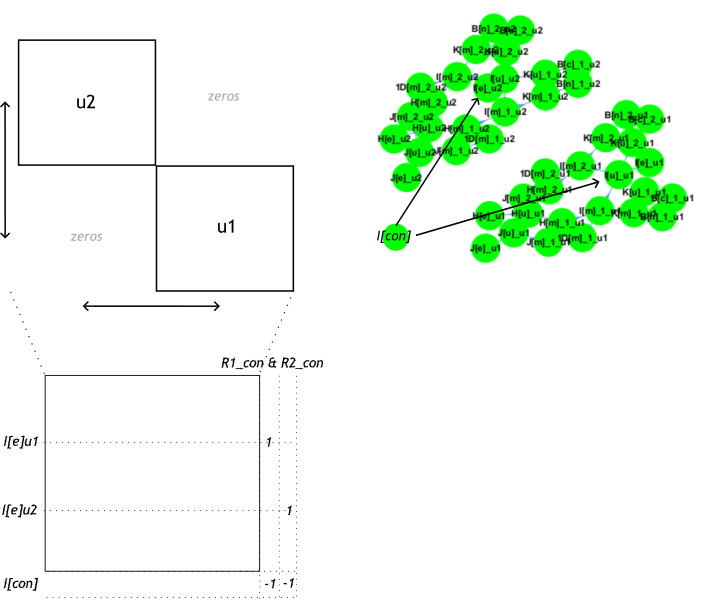

multiple_ele_matrices = 1;
layout_matrix = [1,3;...
                 4,2];
identity_matrices = {[2,4;...
                     8,12],...
                     [1,4;...
                      20,30],...
                     [0,0;
                      0,0],...
                     [1,1;...
                      1,0]};
ele_matrix = [1,0; 4,8];

expand_matrix(layout_matrix, identity_matrices, multiple_ele_matrices)

layout_matrix = [1,2;
                 2,1]

expanded_input_model.S = S;
size(S)
%two_rasters_model.S = [expanded_input_model.S,zeros(size(expanded_input_model.S,1),size(expanded_input_model.S,2));
%                       zeros(size(expanded_input_model.S,1),size(expanded_input_model.S,2)),expanded_input_model.S];
%two_rasters_model.rxns = cellstr([expanded_input_model.rxns + "_u1"; expanded_input_model.rxns + "_u2"]);
%two_rasters_model.mets = cellstr([expanded_input_model.mets + "_u1"; expanded_input_model.mets + "_u2" ]);


function[expanded_matrix] = expand_matrix(layout_matrix, ele_matrix,multiple_ele_matrices)
    %
    % this function does expand a matrix according to another matrix 
    % meaning that the ele matrix will be multiplied by the corresponding
    % element in the layout matrix and then then the matrices are pasted
    % together 
    % say you have:  0 1
    %               -2 0 -> as a layout matrix 
    % then the matrix: 2 2
    %                  3 3 -> as a ele_matrix 
    % will result in: 
    %                  0  0  2  2
    %                  0  0  3  3
    %                 -4 -4  0  0 
    %                 -6 -6  0  0 -> as the expanded matrix!
    %
    % this can also be done in case you want to add a postfix to an matrix:
    %
    % say you have:  "_1" ""
    %                "_2" "" -> as a layout matrix 
    %
    % then the matrix: "rx1" 
    %                  "rx2" -> as a ele_matrix 
    % will result in: 
    %                  rx1_1  ""  ""  ""
    %                  rx2_1  ""  ""  ""
    %                  rx1_2  ""  ""  "" 
    %                  rx2_2  ""  ""  "" -> as the expanded matrix!
    % 
    % parameters: 
    % layout_matrix = eye(number_of_cluster);
    % ele_matrix = internal_S_matrix_for_1_cluster;
    % 
    
    % definition of ifelse function
ternary = @(varargin) varargin{end - varargin{1}};
wanted_dimensions = [size(layout_matrix,1)*size(ele_matrix,1),size(layout_matrix,2)*size(ele_matrix,2)];
if multiple_ele_matrices
    
    a = arrayfun(@(x) ele_matrix{x}', layout_matrix, 'UniformOutput',false);
    if size(layout_matrix,1) == 1
        expanded_matrix = [a{:}];
    end
    
    b= arrayfun(@(x)[a{:,x}]',1:size(layout_matrix,2), 'UniformOutput', false);
    expanded_matrix = [b{:}];
else
    if class(ele_matrix) == "double"
            disp("You have given a numeric elementary matrix!")
            a = arrayfun(@(x) (x.*ele_matrix)', layout_matrix, 'UniformOutput',false);
            if size(layout_matrix,1) == 1
                expanded_matrix = [a{:}];
            elseif size(layout_matrix,1) == 2
                
                b= arrayfun(@(x)[a{:,x}]',1:size(layout_matrix,2), 'UniformOutput', false);
                expanded_matrix = [b{:}];
                
                %b = arrayfun(@(x) reshape([a{:,x}],size(ele_matrix,1),size(ele_matrix,2)*size(layout_matrix,2))', ...
                % 1:size(layout_matrix,2), 'UniformOutput', false);
                %expanded_matrix = [b{:}]';
                %b = arrayfun(@(x) [a{x,:}]', ...
                %             1:size(layout_matrix,2), 'UniformOutput', false);
                %expanded_matrix = reshape([b{:}],size(ele_matrix,1)* size(layout_matrix,1),size(ele_matrix,2)*size(layout_matrix,2));
           
            else
                error('layout matrix is not in the right format! should be a 1xn or 2xn matrix!')
            end
    elseif class(ele_matrix) == "cell" & class(layout_matrix) == "string"
        disp("You have given a character elementary matrix!")
        a = arrayfun(@(x) ternary(x == "",repmat("",size(ele_matrix)),ele_matrix + x), layout_matrix, 'UniformOutput',false);
        expanded_matrix = reshape([a{:}],wanted_dimensions);
        expanded_matrix = arrayfun(@(x) x{:}, expanded_matrix, 'UniformOutput',false);
    else
        error('The layout or/and the elementary matrix do not have the right class! Please check that both of these are in the correct format!! Either only strings or only numeric!!')
    end
    
    if sum(size(expanded_matrix) == wanted_dimensions) ~= 2
        error('The expaned matrix was not expanded into the wanted dimensions, please check why! ')
    end
    
    end
end